close all;

angle_condition = 95.7221726498029;
z_1 = discrete_desired_poles(1)

z_1 =     957.989672782773e-003 + 41.0736282385645e-003i



theta_p = atan2d(imag(z_1), real(z_1))

theta_p =     2.45504225190149e+000


theta_0 = angle_condition + theta_p

theta_0 =     98.1772149017044e+000


zero_PD = real(z_1) - imag(z_1) / tand(theta_0)

zero_PD =     963.891800847064e-003



G_PD = zpk([zero_PD], [0], 1, T);

evalfr(G_p, z_1)

ans =     11.7378553132953e-003 + 117.139441369952e-003i


evalfr(G_PD, z_1)

ans =    -4.31477043014759e-003 + 43.0598081452396e-003i


K_PD = 1 / (abs(evalfr(G_p, z_1)) * abs(evalfr(G_PD, z_1)));

G_PD = K_PD * G_PD

G_PD =
 
  196.28 (z-0.9639)
  -----------------
          z
 
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.



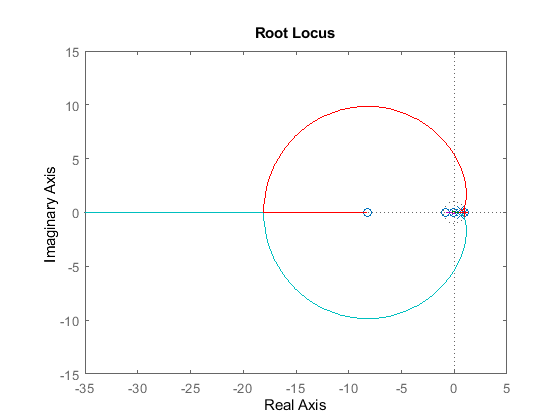


hold on;
rlocus(G_PD * G_p);
scatter(real(discrete_desired_poles), imag(discrete_desired_poles), 'r+');
hold off;

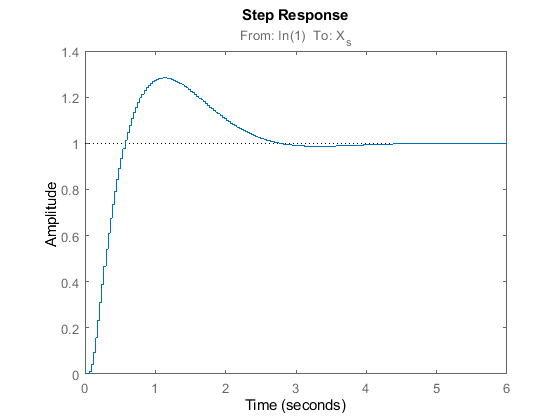


step(feedback(G_p * G_PD, 1))